clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[8.234;22.734;0.020];
u31=[-0.479;-0.552;0.682];
r2=[-7.910;23.296;0.020];
u32=[-0.238;0.691;0.682];
r3=[23.881;23.296;0.020];
u33=[-0.238;0.691;0.682];
r4=[7.910;23.296;22.919];
u34=[0.238;0.691;0.682];
r5=[7.910;23.296;-22.879];
u35=[0.238;0.691;0.682];


x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];

hold on
axis([0 15 0 20]);
for R1=7.3:0.2:9 %离心率
    R3=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     7.3000   18.6000    1.0000


ans =     7.5000   13.6700    1.0000


ans =     7.7000   11.0400    1.0001


ans =     7.9000    9.2700    1.0002


ans =     8.1000    7.9300    1.0002


ans =     8.3000    6.8200    1.0003


ans =     8.5000    5.8500    1.0001


ans =     8.7000    4.9400    1.0001


ans =     8.9000    4.0400    1.0002



plot(x1,y1,'color',[221, 42, 22]/256, ...
    'LineWidth',1.5,'DisplayName','1-2')


for R1=7:0.1:9 %离心率
    R3=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans =     7.0000   18.4700    1.0001


ans =     7.1000   15.6200    1.0001


ans =     7.2000   13.6800    1.0001


ans =     7.3000   12.2300    1.0001


ans =     7.4000   11.0800    1.0001


ans =     7.5000   10.1300    1.0002


ans =     7.6000    9.3300    1.0000


ans =     7.7000    8.6200    1.0002


ans =     7.8000    7.9900    1.0002


ans =     7.9000    7.4200    1.0003


ans =     8.0000    6.9000    1.0001


ans =     8.1000    6.4100    1.0001


ans =     8.2000    5.9500    1.0000


ans =     8.3000    5.5000    1.0004


ans =     8.4000    5.0800    1.0000


ans =     8.5000    4.6600    1.0000


ans =     8.6000    4.2400    1.0003


ans =     8.7000    3.8200    1.0004


ans =     8.8000    3.4000    1.0002


ans =     8.9000    2.9600    1.0002


ans =     9.0000    2.4900    1.0002



plot(x2,y2,'color',[29, 50, 67]/256, ...
    'LineWidth',1.5,'DisplayName','1-3')


for R1=6:0.3:13 %离心率
    R3=14;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans =     6.0000   16.0500    1.0011


ans =     6.3000   15.8000    1.0027


ans =     6.6000   15.6000    1.0001


ans =     6.9000   15.3500    1.0028


ans =     7.2000   15.1500    1.0009


ans =     7.5000   14.9000    1.0038


ans =     7.8000   14.7000    1.0017


ans =     8.1000   14.4500    1.0041


ans =     8.4000   14.2500    1.0013


ans =     8.7000   14.0000    1.0028


ans =     9.0000   13.7500    1.0037


ans =     9.3000   13.5000    1.0038


ans =     9.6000   13.2500    1.0032


ans =     9.9000   13.0000    1.0017


ans =    10.2000   12.7000    1.0038


ans =    10.5000   12.4500    1.0005


ans =    10.8000   12.1500    1.0005


ans =    11.1000   11.8000    1.0036


ans =    11.4000   11.5000    1.0012


ans =    11.7000   11.1500    1.0016


ans = 1×3
   12.0000   10.8000    1.0006


ans = 1×3
   12.3000   10.4000    1.0019


ans = 1×3
   12.6000   10.0000    1.0014


ans = 1×3
   12.9000    9.5500    1.0026



plot(x3,y3,'color',[84, 130, 53]/256, ...
    'LineWidth',1.5,'DisplayName','1-4')


for R1=6:0.3:13 %离心率
    R3=14;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];   
end

ans = 1×3
    6.0000   16.6400    1.0003


ans = 1×3
    6.3000   16.3200    1.0006


ans = 1×3
    6.6000   16.0300    1.0001


ans = 1×3
    6.9000   15.7500    1.0001


ans = 1×3
    7.2000   15.4800    1.0002


ans = 1×3
    7.5000   15.2100    1.0009


ans = 1×3
    7.8000   14.9600    1.0001


ans = 1×3
    8.1000   14.7000    1.0003


ans = 1×3
    8.4000   14.4400    1.0005


ans = 1×3
    8.7000   14.1800    1.0005


ans = 1×3
    9.0000   13.9200    1.0002


ans = 1×3
    9.3000   13.6500    1.0003


ans = 1×3
    9.6000   13.3700    1.0007


ans = 1×3
    9.9000   13.0900    1.0004


ans = 1×3
   10.2000   12.8000    1.0002


ans = 1×3
   10.5000   12.4900    1.0008


ans = 1×3
   10.8000   12.1800    1.0005


ans = 1×3
   11.1000   11.8500    1.0007


ans = 1×3
   11.4000   11.5100    1.0006


ans = 1×3
   11.7000   11.1600    1.0000


ans = 1×3
   12.0000   10.7800    1.0004


ans = 1×3
   12.3000   10.3800    1.0007


ans = 1×3
   12.6000    9.9700    1.0001


ans = 1×3
   12.9000    9.5200    1.0005


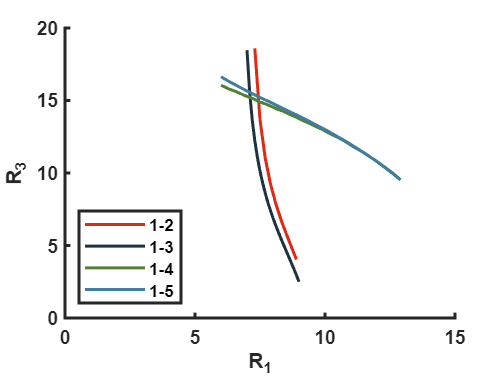


plot(x4,y4,'color',[63, 125, 162]/256, ...
    'LineWidth',1.5,'DisplayName','1-5')



set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','southwest');

hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end
